EEG signals of 4 part of the head such as P4,Cz,F8 and T7.  Dataset has 20 subjects and 8(1,2,5,6,7,8,9,10) different experiments where experiment 1,2 has three sessions for each subject. 

In the matlab live script, we will observe the frequency response corresponding with the subject.

% Suppress the warning about modified column headers
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');

Checking dataset...

datasetlist(1,10);

Frequency_ex01_Central.xlsx
Frequency_ex01_Frontal.xlsx
Frequency_ex01_Periferal.xlsx
Frequency_ex01_Temporal.xlsx
Frequency_ex02_Central.xlsx
Frequency_ex02_Frontal.xlsx
Frequency_ex02_Periferal.xlsx
Frequency_ex02_Temporal.xlsx
Frequency_ex05_Central.xlsx
Frequency_ex05_Frontal.xlsx
Frequency_ex05_Periferal.xlsx
Frequency_ex05_Temporal.xlsx
Frequency_ex06_Central.xlsx
Frequency_ex06_Frontal.xlsx
Frequency_ex06_Periferal.xlsx
Frequency_ex06_Temporal.xlsx
Frequency_ex07_Central.xlsx
Frequency_ex07_Frontal.xlsx
Frequency_ex07_Periferal.xlsx
Frequency_ex07_Temporal.xlsx
Frequency_ex08_Central.xlsx
Frequency_ex08_Frontal.xlsx
Frequency_ex08_Periferal.xlsx
Frequency_ex08_Temporal.xlsx
Frequency_ex09_Central.xlsx
Frequency_ex09_Frontal.xlsx
Frequency_ex09_Periferal.xlsx
Frequency_ex09_Temporal.xlsx
Frequency_ex10_Central.xlsx
Frequency_ex10_Frontal.xlsx
Frequency_ex10_Periferal.xlsx
Frequency_ex10_Temporal.xlsx


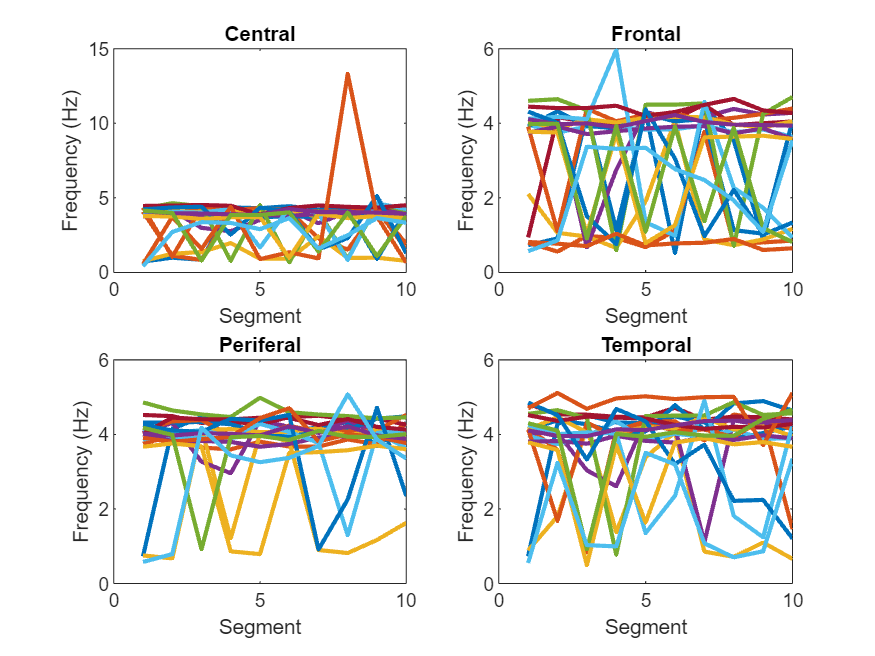

drawfigure(10,10);

function datasetlist(x,y)
    directoryPath = 'K:\Father Fourier Analysis Report\';
    for i = x:y
        if i == 3 || i == 4
            continue
        else
            if i==10
                pattern = 'ex10';
            else
                pattern = strcat('ex0',num2str(i));
            end
        end
        filesInfo = dir(fullfile(directoryPath, ['Frequency_' pattern '*.xlsx']));
        for j = 1:numel(filesInfo)
            disp(filesInfo(j).name);
        end
    end
end

function drawfigure(x,y)
    directoryPath = 'K:\Mother Fourier Analysis Report\';
    for i = x:y
        if i == 3 || i == 4
            continue
        else
            if i==10
                pattern = 'ex10';
            else
                pattern = strcat('ex0',num2str(i));
            end
        end
        filesInfo = dir(fullfile(directoryPath, ['Frequency_' pattern '*.xlsx']));
    
        figure(i);
        % Display the list of files
        n = 1;
        for j = 1:numel(filesInfo)
            dataTable = readtable(fullfile(directoryPath,filesInfo(j).name));
            s = length(filesInfo(j).name);
            x = filesInfo(j).name;
            attributeType = x(16:s-5);
            if dataTable.SessionName == 0
                subplot(2,2,j);
                for k = 1:20
                    dataTableX = dataTable(k, {'Seg0', 'Seg1', 'Seg2', 'Seg3', 'Seg4', 'Seg5', 'Seg6', 'Seg7', 'Seg8', 'Seg9'});
                    dataTableY = table2array(dataTableX);
                    plot(1:10,dataTableY,'LineWidth', 2);
                    hold on
                end
                xlabel('Segment');
                ylabel('Frequency (Hz)');
                title(attributeType);
                hold off  
            else
                
                for l = 1:3
                    subplot(4,3,n);
                    for k = 1:20
                        dataTableX = dataTable(dataTable.SessionName == l, {'Seg0', 'Seg1', 'Seg2', 'Seg3', 'Seg4', 'Seg5', 'Seg6', 'Seg7', 'Seg8', 'Seg9'});
                        dataTableY = table2array(dataTableX);
                        plot(1:10,dataTableY,'LineWidth', 2);
                        hold on
                    end
                    xlabel('Segment');
                    ylabel('Frequency (Hz)');
                    title(attributeType);
                    hold off
                    n = n + 1;
                end
            end
        end
    end
end
